Diseño de transformador monofasico 

con los siguientes parametros:

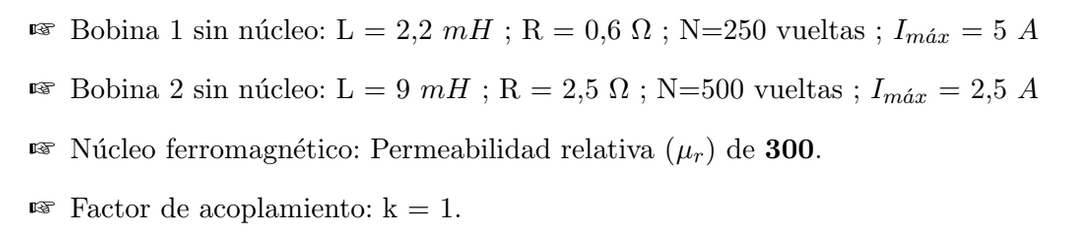

clc, clear, close all
format short g

vp = [10:1:120];
f = 60;
w = 2*pi*f;
k = 1;

%datos del nucleo ferromagnetico
u = 300;
%datos de las bobinas
L1 = 2.2e-3;
L2 = 9e-3;

N1 = 250;
N2 = 500;

n = N2/N1 %razon de vueltas (relacion de transformación)

n =      2


vs = (N2*vp)/N1 %tension en la bobina secundaria

vs =     20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100   102   104   106   108   110   112   114   116   118


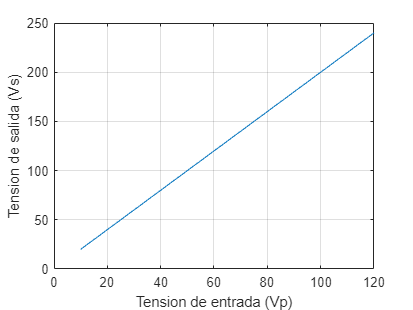

plot(vp,vs)
grid on
xlabel("Tension de entrada (Vp)")
ylabel("Tension de salida (Vs)")

comprobamos con el simulador:

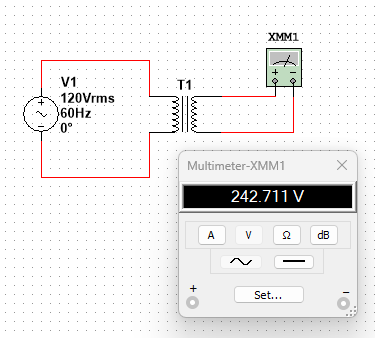

calculamos las corrientes:

I1_max = 5;
I2_max = 2.5;

teniendo en cuenta la corriente maxima en la bobina 1 y 2, calculamos la potencia que pueden disipar:

vp = 120;

p1 = vp*I1_max %[W]

p1 =    600


p2 = vp*n*I2_max %[W]

p2 =    600


para no superar los limites de corriente admitidos calcular la autoinductancia de las bobinas:

u0 = 4*pi*10e-7; %permitividad del aire
s_l1 = L1/(u0*(N1^2)) %relacion s/l de la autoinductancia

s_l1 =     0.0028011


s_l2 = L2/(u0*(N2^2)) %relacion s/l de la autoinductancia

s_l2 =     0.0028648


inductancia de la bobina secundaria junto con el nucleo ferro magnetico

L1_nuevo = (N1^2)*(u0*u)*s_l1 %[H]

L1_nuevo =          0.66


L2_nuevo = (N2^2)*(u0*u)*s_l2 %[H]

L2_nuevo =           2.7


calculamos las corrientes con estas nuevas inductancias:

vp=10

vp =     10


xl1 = w*L1_nuevo;
I1 = vp/xl1 %[A]

I1 =      0.040191


Lo verificamos en el simulador:

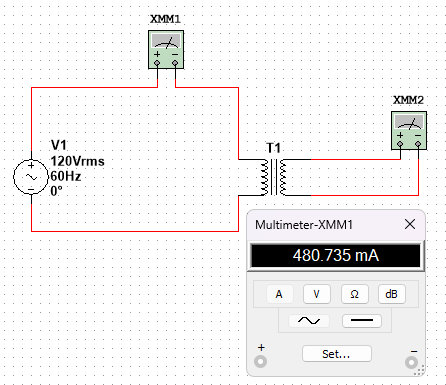

Y como la segunda bobina esta en circuito abierto, no tenemos corriente solo tension.

**Comporbacion de manera inversa**

L1 = 9e-3;
L2 = 2.2e-3;

N1 = 500;
N2 = 250;
n = N2/N1 %razon de vueltas (relacion de transformación)

n =           0.5


vs = (N2*vp)/N1 %[V] tension en la bobina secundaria

vs =      5


verificamos en el simulador:D

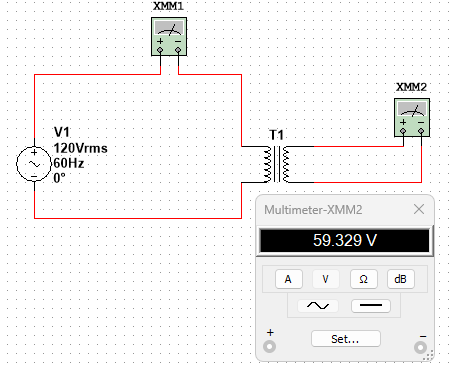

para no superar los limites de corriente admitidos calcular la autoinductancia de las bobinas:

s_l1 = L1/(u0*(N1^2)) %relacion s/l de la autoinductancia

s_l1 =     0.0028648


s_l2 = L2/(u0*(N2^2)) %relacion s/l de la autoinductancia

s_l2 =     0.0028011


inductancia de las bobinas junto con el nucleo ferro magnetico

L1_nuevo = (N1^2)*(u0*u)*s_l1 %[H]

L1_nuevo =           2.7


L2_nuevo = (N2^2)*(u0*u)*s_l2 %[H]

L2_nuevo =          0.66


xl1 = w*L1_nuevo;
I1 = vp/xl1 %[A]

I1 =     0.0098244


verificamos en el simulador